clear
clc

# Estimating Outcomes in Annual- Perennial Model 

The fundamental quantities to estimate are

- $\lambda_i$ for each species, which depends only on demography,

- $\alpha_i$ for each species, which we infer based on total population size

- $b_i$, which depends on the biomass of plants and how much litter released

- $L^*$, the estimates of tolerance to litter.

Each are estimated in seperate sections below.

## Estimating $\lambda$

The reproductive number for the annual is

    $\lambda_A = \frac{g_Ae_Ay_A}{1-s_A(1-g_A)}$.

We have the following estimates from the literature (and their sources):

sA = 0.15; % Redwood et al. (2018);  
gA = 0.79;  yA = [6000 7000]; % Wilson et al. (2015)
eA = [0.53 0.96]; % Emery et al. (2013); Warren et al. (2013)

There is uncertainty in the basic reproductive number because we have a range of values for *y**A* and *e**A*. One way to characterize this uncertainty is by the minimum, median, and maximum values of the distribution. 

lambdaA_median = mean(yA)*gA*mean(eA)/(1 - sA*(1-gA));
lambdaA_minmax = yA*gA.*eA/(1 - sA*(1-gA));
lambdaA = [lambdaA_minmax(1),lambdaA_median, lambdaA_minmax(2)]

lambdaA = 	1.0e+03 *

    2.5939    3.9500    5.4815


The reproductive number for the perennial is 

    $\lambda_P = \frac{g_Pe_Py_P}{1-s_P(1-g_P)}\left(f + \frac{p_1}{1-p_2} \right)$.

We have the following estimates from the literature (and their sources), with indication whether the value was from a species in the genus *Elymus* or from another perennial species:

sP = 0.05; gP = 0.8; % Garrison and Stier (2010)  *Elymus value
yP = [390,435];  % Stevens (1957) *Elymus value
p2 = [0.8,0.97]; eP = [0.3,0.51]; % Lauenroth and Adler (2008) *Non-Elymus grass
f = 0; p1 = p2; % Both assumed.

Again, we will calculate the minimum, median, and maximum values of lambda.

lambdaP_minmax = gP.*yP.*eP.*(f + fliplr(p1)./(1-fliplr(p2)))./(1 - fliplr(sP).*(1-gP));
lambdaP_median = mean(gP)*mean(yP)*mean(eP)*(mean(p1)/(1-mean(p2)))/(1 - mean(sP)*(1-mean(gP)));
lambdaP = [lambdaP_minmax(1), lambdaP_median, lambdaP_minmax(2)]

lambdaP = 	1.0e+03 *

    3.0570    1.0389    0.7171


Using these distributions of $\lambda$s, who is the dominant competitor in the absence of litter? 

The ratio's of reproductive numbers give an indication of who is dominant. 

lambda_ratio = lambdaA'./lambdaP

lambda_ratio =     0.8485    2.4968    3.6173
    1.2921    3.8021    5.5084
    1.7931    5.2762    7.6440


Here is a plot of the range of estimates of lambda for each species.

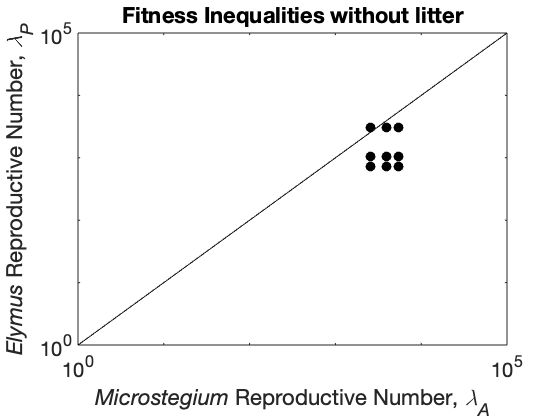

lambda_max = max([lambdaA, lambdaP]);
loglog([1,20*lambda_max], [1,20*lambda_max], 'color', 'black');
hold on
for i = 1:length(lambdaA)
    scatter(lambdaA(i)*ones(1,length(lambdaP)), lambdaP,...
        100, 'filled', 'CData', zeros(1,3))
end
hold off
xlabel('{\itMicrostegium} Reproductive Number, {\it\lambda_A}');
ylabel('{\itElymus} Reproductive Number, {\it\lambda_P}')
set(gca, 'FontSize', 20);
title('Fitness Inequalities without litter')
axis([1, 10^5, 1, 10^5])

It looks here like most of our evidence suggests that *Microstegium* is a better competitor than *Elymus*, which fits with our prior expectations.

## Comparing Densities Expected in Monoculture

The next step is to calculate the values of *α*. The value of *α* in the model is presented as a per-seedling effect, which can be estimated using competition experiments. However, these are very sensitive to the scale of the experiments and the densities of the plants used. That said, *α *has the only practical role in the model of scaling equilibrium plant density. It plays almost no role in coexistence of species, except indirectly through litter production. Instead of calculating these directly, we use estimates of population density in nature to fit values of *α. *

We have estimates of biomass density of plants, so in the following, we rewrite the model in terms of biomass. Doing so changes nothing about the dynamics of the model, it only changes the units. Let $X_A = x_Ag_AE_AN_A$ be the biomass density of annual plants, where $x_A$ is the biomass of an individual annual. Let $X_P = x_PN_P$ be the biomass density of the established perennials where $x_P$ is the biomass of a single individual, and let $X_S = x_P\gamma g_PE_PN_S$ be the biomass density of the first-year perennials, where $\gamma <1$ now takes the interpreation as the fractional biomass of a first year plant compared to plants beyond their first year.

Writing the competition function in terms of biomass yields

    $C = 1 + \frac{\alpha_A}{x_A}X_A + \frac{\alpha_P}{x_P}(X_P + X_S)$.

Define $\alpha_A^x = \alpha_A/x_A$ as the annual competition coefficient in units of biomass density and $\alpha_P^x = \alpha_P/x_P$ as the perennial competition coefficient in units of biomass density. The competition function can now be written as 

    $C = 1 + \alpha_A^xX_A + \alpha_P^x(X_P+X_S)$.

When the annual is growing alone at equilibrium, $\hat{C}^{\{-P\}} = \lambda_A/(1+\beta_A\hat{L}^{\{-P\}})$ (S14). The equilibrium competition in this scenario is $\hat{C}^{\{-P\}} = 1 + \alpha_A^x\hat{X}_A^{\{-P\}}$. Under the assumption that litter density is small, we have the following approximation for the biomass-specific competition coefficient:

    $\alpha^x_A =  \frac{\lambda_A - 1}{\hat{X}_A}$.

It thus suffices that $\alpha_A^x$ can be estimated with $\lambda_A$ and the equilibrium biomass density given there is little influence of litter. An estimate of $\alpha_A^x$ is 

    $\alpha_A^x = \text{exp}\left \{ \text{ln}[\lambda_A - 1] - \overline{\text{ln}[\text{biomass density}]} \right \}$.

where an overbar is a simple average. 

Flory et al. (2017) experimentally introduced *Microstegium *into 5m x 5m plots and kept control plots with just native species and harvested biomass each year in subsets of the plots. In the first few years, *Microstegium *was near 100% of the biomass in these plots and so they are an effective measure of monoculture densities. Furthermore, we expect little influence of litter in the first few years given that the plots were cleared prior to the start of the experiment. We used data on biomass in the invaded plots in the first 4 years of the study (2006-2009). The mean biomass density on the log scale during these year is

ln_micro_biomass_density = 5.8219; % units: log(grams/m^2)
micro_biomass_density = exp(ln_micro_biomass_density) %units: inds/m^2

micro_biomass_density = 337.6129

Hence, an estimate for $\alpha_A^x$ is

alphaA_biomass = (lambdaA - 1)/exp(ln_micro_biomass_density) 

alphaA_biomass =     7.6801   11.6968   16.2330


%units: m^2/inds;

Using the same approach for *Elymus*, recognize that total perennial biomass at equilibrium is (assuming $L \approx 0$ and $N_A = 0$) 

    $\alpha_P^x = \frac{\lambda_P-1}{\hat{X}_P+\hat{X}_S}$ .

We use graminoid biomass in all years from the uninvaded, control plots in Flory et al. (2017) as biomass density. The biomass density there is 

ln_elymus_biomass_density = 4.8343; 
% units:log(grams/m^2)
elymus_biomass_density = exp(ln_elymus_biomass_density) %units: inds/m^2

elymus_biomass_density = 125.7505

This means that the estimate for $\alpha_P^x$ is 

alphaP_biomass = (lambdaP_minmax - 1)./exp(ln_elymus_biomass_density)

alphaP_biomass =    24.3018    5.6945


%units: m^2/inds;

Instead of using these estimates, we use the functional relationship between *αA*and equilibrium plant to create the coexistence diagrams. This is because we need to create invasion boundaries as a function of *λA* and *λP*. Hence, the actual values of *αA* change in those diagrams as *λA* is varied but plant density remains fixed. 

## Litter sensitivity and production

The final parameters to estimate are sensitivity to litter, $\beta_i$, and litter production values, $b_i$. 

To find the correct estimates for litter production, it's informative to consider the litter (equation 4 of the main text) when written in terms of biomass density rather than individual density, which is

    $L(t+1) = (1-d)L(t) + X_A(t) + \frac{b_P}{x_P}(X_P(t) + X_S(t)) + B_T$.

(For completeness, we have included contributions from both first-year and established perennials). On this scale, the litter production value for the annual is 1 (the litter production value is a redundnat parameter when the model state variables are plant biomass since all the biomass is converted to litter) and the litter production value for the perennial is $b_P/x_P$. In a greenhouse experiment, 55% of *Elymus *biomass was dead at the end of the growing season (Amy E. Kendig, unpublished data), i.e., $b_P/x_P$ = 0.55. 

bP_over_xP = 0.55;

To find the estimates for litter sensitivity, we used data from a previous experiment in the greenhouse. Benitez et al. (2021) planted seeds of *M.* *vimineum* and *E*. *virginicus* in pots with different litter densities (0, 50, 100, and 200 g/m2) and tracked establishment of plants. For *M. viimineum*, they found the following average establishment fractions in each treatment.

Ev_establishment = [0.84,0.745,0.74,0.76];
Mv_establishment = [0.86,0.85,0.76,0.71];
litter_densities = [0,50,100,200]; %units of g/m2

We estimated $e_i$ and $\beta_i$ using nonlinear regression and minimizing OLS error. 

modelfun = @(b,x)b(1)./(1+b(2)*x);
Ev_E_model = fitnlm(litter_densities, Ev_establishment, modelfun, [0.8, 0.001])

Ev_E_model = Nonlinear regression model:
    y ~ b1/(1 + b2*x)

Estimated Coefficients:
           Estimate         SE         tStat      pValue  
          __________    __________    _______    _________

    b1        0.8006      0.037057     21.604    0.0021356
    b2    0.00044726    0.00045134    0.99096      0.42615


Number of observations: 4, Error degrees of freedom: 2
Root Mean Squared Error: 0.0465
R-Squared: 0.336,  Adjusted R-Squared 0.00414
F-statistic vs. zero model: 550, p-value = 0.00181

Mv_E_model = fitnlm(litter_densities, Mv_establishment, modelfun, [0.8, 0.001])

Mv_E_model = Nonlinear regression model:
    y ~ b1/(1 + b2*x)

Estimated Coefficients:
          Estimate         SE        tStat       pValue  
          _________    __________    ______    __________

    b1       0.8702      0.020793    41.851    0.00057045
    b2    0.0011544    0.00027214    4.2418      0.051336


Number of observations: 4, Error degrees of freedom: 2
Root Mean Squared Error: 0.0251
R-Squared: 0.92,  Adjusted R-Squared 0.879
F-statistic vs. zero model: 2.01e+03, p-value = 0.000497

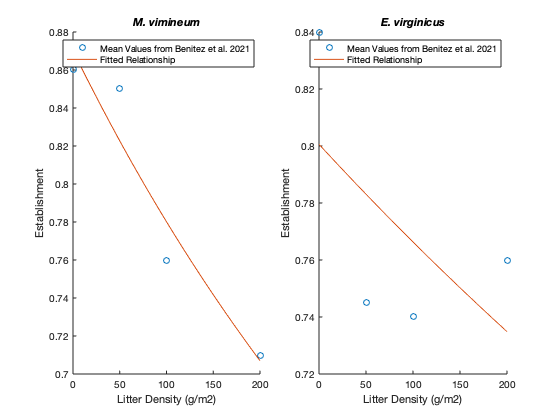

betaA = table2array(Mv_E_model.Coefficients(2,1));
betaP = table2array(Ev_E_model.Coefficients(2,1));

figure()
subplot(1,2,1)
scatter(litter_densities, Mv_establishment)
hold on; Mv_predict = predict(Mv_E_model, [0:200]');
plot(0:200, Mv_predict); hold off;
legend('Mean Values from Benitez et al. 2021', 'Fitted Relationship')
xlabel('Litter Density (g/m2)'); ylabel('Establishment');
title('\itM. vimineum');
subplot(1,2,2)
scatter(litter_densities, Ev_establishment);
hold on; Ev_predict = predict(Ev_E_model, [0:200]');
plot(0:200, Ev_predict); hold off;
legend('Mean Values from Benitez et al. 2021', 'Fitted Relationship')
xlabel('Litter Density (g/m2)'); ylabel('Establishment');
title('\itE. virginicus');

Now we can calculate L*s for the species

LstarA = (lambdaA - 1)/betaA

LstarA = 	1.0e+06 *

    2.2462    3.4209    4.7475


LstarP = (lambdaP - 1)/betaP

LstarP = 	1.0e+06 *

    6.8327    2.3206    1.6011


The ratio of litter sensitivities is 

beta_ratio = betaA./betaP

beta_ratio = 2.5810

And L*s plotted against one another show that *Elymus *is, in general, a dominant competitor in the presence of litter. 

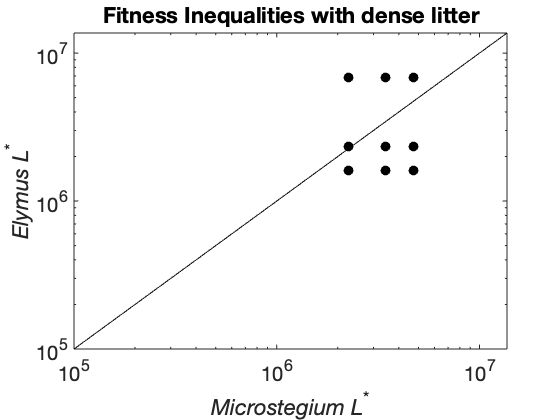

Lstar_max = max([LstarA, LstarP]);
figure()
loglog(2*[1,Lstar_max], 2*[1,Lstar_max], 'color', 'black');
hold on
for i = 1:length(LstarA)
    scatter(LstarA(i)*ones(1,length(LstarP)), LstarP,...
        100, 'filled', 'CData', zeros(1,3))
end
hold off
xlabel('{\itMicrostegium L}^*'); ylabel('{\itElymus L}^*')
set(gca, 'FontSize', 20); axis([100000,2*Lstar_max, 100000, 2*Lstar_max])

title('Fitness Inequalities with dense litter')

## Comparing Competitive Hierarchies and Litter Hierarchies

We can compare the competitive hirearchies both in the presence and absence of litter by plotting the ratio $L_A^*/L_P^*$ against $\lambda_A/\lambda_P$ on a log-scale. 

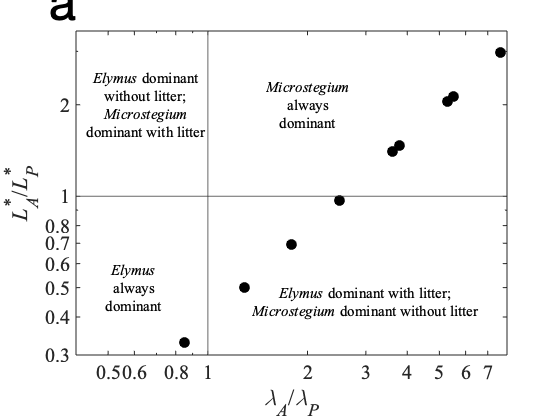

Lstar_ratio = ones(3,1)*LstarA./(LstarP'*ones(1,3));
Lambda_ratio = ones(3,1)*lambdaA./(lambdaP'*ones(1,3));
figure()
loglog(reshape(Lambda_ratio, 9, 1), reshape(Lstar_ratio, 9, 1),...
    'o', 'MarkerSize', 10, 'MarkerFaceColor', 'Black',...
    'MarkerEdgeColor','black');
axis([0.4,8,0.3,3.5])
xline(1); yline(1); ax = gca; ax.FontSize = 20;
xlabel('{\it\lambda_A}/{\it\lambda_P}')
ylabel('{\itL^*_A}/{\itL^*_P}');
set(gca,'FontName', 'Times New Roman')
t1 = text(3,0.45, {'{\itElymus} dominant with litter;',...
    '{\itMicrostegium} dominant without litter'},...
    'HorizontalAlignment',"center");
t2 = text(2,2, {'{\itMicrostegium}', 'always', 'dominant'},...
    'HorizontalAlignment',"center");
t3 = text(0.6,0.5, {'{\itElymus}','always','dominant'},...
    'HorizontalAlignment',"center");
t4 = text(0.65,2, {'{\itElymus} dominant', 'without litter;',...
    '{\itMicrostegium}', 'dominant with litter'},...
    'HorizontalAlignment',"center");
set([t1,t2,t3,t4], {'FontSize'}, {15})
set([t1,t2,t3,t4], {'FontName'}, {'Times New Roman'})
ax = gca; ax.XTick = [0.5,0.6,0.8,1,2,3,4,5,6,7];
ax.YTick = [0.1,0.2,0.3,0.4,0.5,0.6,0.7,0.8,1,2];
txt = text(0,1,'a', 'Units', 'Normalized', 'HorizontalAlignment', 'right');
txt.FontSize = 50;
txt.VerticalAlignment = 'bottom';

A conclusion here is that most of the evidence here points to a tradeoff in performance in environments where litter is present and environments with litter absent. At the boundaries of our estimates, we predict that one species is dominant across both conditions. The tradeoff is such that the invasive species, *Microstegium*, is dominant in the absence of litter. 

## Species Coexistence Outcomes

The outcome of coexistence depends on the litter accumulated for each species as resident in the presence of litter produced by trees. The final unspecified values of the model are decomposition, *d*, and tree litterfall, *B**T*. We chose *d* = 0.1 but note that choosing an alternative value does not qualitatively change the results. We chose two values of *B**T *corresponding to no litter from other sources (*B**T* = 0) and moderate extra litter (*B**T* = 200 *g*/*m*2). 

We have to find the invasion boundaries, which have the general form, for species *i,*

    $\lambda_i > \lambda_j \frac{1+\beta_i\hat{L}^{\{-i\}}}{1+\beta_j\hat{L}^{\{-i\}}}$.                (2)

Because we have rewritten the model in terms of biomass density, we substitute $\alpha_A^x = \alpha_A/b_A $ ($= \alpha_A/x_A$) in the expression for $\hat{L}^{\{-P\}}$ to give

    $\hat{L}^{\{-P\}} = -0.5\left( \frac{1}{\alpha^x_Ad} + \frac{1}{\beta_A} - \frac{B_T}{d}   \right) + \sqrt{\frac{1}{4} \left( \frac{1}{\alpha^x_Ad} + \frac{1}{\beta_A} - \frac{B_T}{d}   \right)^2 + \frac{B_T}{d} + \frac{1}{d}\frac{(\lambda_A- 1)}{\alpha_A^x \beta_A}  } $.

For the perennial we substitute $\alpha_P^x/x_b = \alpha\prime_P$ in the expression for $\hat{L}^{\{-A\}}$ to give

    
$$\hat{L}^{\{-A\}} = -0.5\left( \frac{b_P}{x_P}\frac{1}{\alpha^x_Pd} + \frac{1}{\beta_P} - \frac{B_T}{d}   \right) + \sqrt{\frac{1}{4} \left( \frac{b_P}{x_P}\frac{1}{\alpha^x_Pd} + \frac{1}{\beta_P} - \frac{B_T}{d}   \right)^2 + \frac{B_T}{d} + \frac{b_P}{x_P}\frac{1}{d}\frac{(\lambda_P - 1)}{\alpha_P^x \beta_P}  }$$


where we estimated that $b_P/x_P$ = 0.55 above. 

To create these lines, we create a vector of values for $\lambda_j$ and calculate values of $\hat{L}^{\{-i\}}$ across the vector. This creates a vector of values for the right hand side of the inequality (2) above.

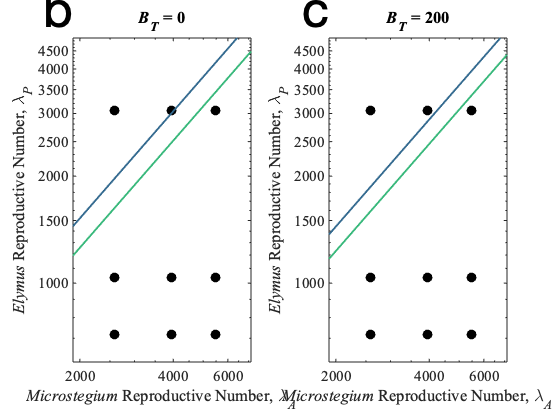

colors = viridis(4);    %Defining colors to plot the lines
colors = colors(2:3,:); %Defining colors to plot the lines

% Values of decomposition and tree litterfall to use in the panels.
dvec = 0.1*ones(1,2);  BTvec = [0,200];

% Values of relative sensitivity of Elymus to litter.
rel_mag = [0.5, 1, 2];
% Differe line types for the different values of elymus relative density.
LTYPE = {'--', '-', ':'};
LABEL = {'b', 'c'};

t = tiledlayout(1,2);
% Loop over the four possible combinations of d and B_T
for k = 1:2
    
    % Set the values of d and BT
    d = dvec(k); BT = BTvec(k);
   
    nexttile
    
    % Create axes
    loglog(0,0,'Color','none', 'HandleVisibility','off');
    xlabel('{\itMicrostegium} Reproductive Number, \lambda_{\itA}');
    ylabel('{\itElymus} Reproductive Number, \lambda_{\itP}')
    hold on
    % Plot the estimates of lambda_A and lambda_P
    for i = 1:length(lambdaA)
        scatter(lambdaA(i)*ones(1,length(lambdaP)), lambdaP,...
            100, 'filled', 'CData', zeros(1,3))
    end
    hold off
    set(gca, 'FontSize', 15); set(gca, 'FontName', 'Times New Roman');
    axis([1900, 1.3*max(lambdaA), 600, 1.6*max(lambdaP)])

    % Define a vector of values of lambda to create lines
    lambda_vec = linspace(0,10*lambda_max, 1000);
    
    %% Plot elymus invasion boundary
    hold on
    % Loop over the three values of elymus relative density
    
    for i = 2
        betaP_act = betaP*rel_mag(i);
        % Calculate the density of litter produced by microstegium at equilbirium
        alphaAx = (lambda_vec - 1)/(micro_biomass_density);
        bA = 1;
        Leq_A = LitterEq(lambda_vec, alphaAx, betaA, bA/d, BT);
        % Find the critical values of elymus lambda required to invade.
        lambda_P_crit = lambda_vec.*(1+betaP_act*Leq_A)./(1+betaA*Leq_A);
        % Plot this line
        loglog(lambda_vec, lambda_P_crit, LTYPE{i}, 'Color', colors(2,:),...
            'LineWidth', 2);
    
        % Now do the same for the invasion boundary of microstegium
        % Calculate elymus competition coefficient with relative density
        % value
        bP = bP_over_xP;
        alphaPx = (lambda_vec - 1)/(elymus_biomass_density);
        % Calculate eq litter produced by elymus as resident
        Leq_P = LitterEq(lambda_vec, alphaPx, betaP_act, bP/d, BT);
        % Calculate critical values of lambda needed for Microstegium to
        % invade
        lambda_A_crit = lambda_vec.*(1+betaA*Leq_P)./(1+betaP_act*Leq_P);
        % Plot these critical invasion values 
        loglog(lambda_A_crit, lambda_vec, LTYPE{i}, 'Color', colors(1,:),...
            'LineWidth', 2)
    end
    hold off
    % Label the plot
    title(['{\itB_T} = ', num2str(BT)]);
    t = text(0,1,LABEL{k}, 'Units', 'Normalized', 'HorizontalAlignment', 'right');
    t.FontSize = 50;
    t.VerticalAlignment = 'bottom';
end

References Cited

Benitez, L., A. E. Kendig, A. Adhikari, K. Clay, P. F. Harmon, R. D. Holt, E. M. Goss, and S. L. Flory. 2021. Invasive grass litter suppresses native species and promotes disease. bioRxiv 2021.04.07.437244; doi: https://doi.org/10.1101/2021.04.07.437244

Emery, S. M., S. L. Flory, K. Clay, J. R. Robb, and B. Winters. 2013. Demographic responses of the invasive annual grass Microstegium vimineum to prescribed fires and herbicide. Forest Ecology and Management 308:207–213.

Flory, S. L., J. Bauer, R. P. Philips, and K. Clay. 2017. Effects of a non-native grass invasion decline over time. Journal of Ecology 105:1457-1484.

Garrison, M. A., and J. C. Stier. 2010. Cool-season turfgrass colony and seed survival in a restored prairie. Crop Science 50:345–356.

Lauenroth, W. K., and P. B. Adler. 2008. Demography of perennial grassland plants: Survival, life expectancy and life span. Journal of Ecology 96:1023–1032.

Redwood, M. E., G. R. Matlack, and C. D. Huebner. 2018. Seed longevity and dormancy state suggest management strategies for garlic mustard (Alliaria petiolata) and Japanese stiltgrass (Microstegium vimineum) in deciduous forest sites. Weed Science 66:190–198.

Stevens, O. A. 1957. Weights of seeds and numbers per plant. Weeds 5:46–55.

Warren, R. J., V. Bahn, and M. A. Bradford. 2013. Decoupling litter barrier and soil moisture influences on the establishment of an invasive grass. Plant and Soil 367:339–346.

Wilson, C. H., T. T. Caughlin, D. J. Civitello, and S. L. Flory. 2015. Combining mesocosm and field experiments to predict invasive plant performance: A hierarchical Bayesian approach. Ecology 96:1084–1092.